# Example 12.1: `Four-Channel ``FDOA`` Solution`

Nicholas O'Donoughue 1 July 2019

`Consider an example four-channel ``FDOA`` system with three sensors equally spaced along a 10-km radius circle, centered on a reference sensor. Each is moving away from the origin at 100 m/s (with the center reference center moving in the +x direction). The locations are plotted in Figure 12.7. In this example, there is an emitter roughly 50 km from the central reference center, marked with a triangle. We assume that each sensor achieves a standard deviation of 3 Hz on frequency estimation. Generate solutions from a single set of timing measurements at the four sensors, using each of the approaches discussed in this chapter.`

## Solution

`We begin by defining the sensor and source positions`

baseline           = 10e3;    % m
sensor_velocity    = 100; % m/s
num_sensors        = 4;
ref_sensor_idx     = 4; assert(ref_sensor_idx > 0 && ref_sensor_idx <= num_sensors,'Bad reference sensor index.');
sensor_rotation    = pi/2;
sensor_pos_angle = (0:num_sensors-1)*2*pi/(num_sensors-1) + sensor_rotation;
x_sensor = baseline * [ cos(sensor_pos_angle);sin(sensor_pos_angle)];
v_sensor = sensor_velocity * [ cos(sensor_pos_angle);sin(sensor_pos_angle)];

% Move one of the duplicate positions to the origin
x_sensor(:,end) = 0;
v_sensor(:,end) = [sensor_velocity;0]; % Sensor at origin moving in +x

% Define Sensor Performance
freqError     = 3; % Hz resolution
transmit_freq = 1e9; % Hz
rngRateStdDev = freqError*utils.constants.c/transmit_freq;
C_rr = rngRateStdDev^2*eye(num_sensors); % covariance matrix structure
Crrdoa = utils.resampleCovMtx(C_rr,ref_sensor_idx);

% Initialize Transmitter Position
source_angle = rand(1)*2*pi;
source_baseline_mult = 5;
x_source = source_baseline_mult*baseline*[cos(source_angle);sin(source_angle)];

`Next, we generate a set of range rate difference measurements`

% Generate noise free measurement
rho_dot_true = fdoa.measurement(x_sensor,v_sensor,x_source,ref_sensor_idx);

% Generate noisy measurements
num_monte_carlo = 1000;
L = chol(Crrdoa,'lower');
num_msmt=size(L,1);
noise = L*randn(num_msmt,num_monte_carlo);
rho_dot = rho_dot_true + noise; % Noisy sample vector

`Then, for each of the Monte Carlo iterations, we call the ``FDOA`` solvers.`

% Initial Target Position Estimate
init_angle_offset = pi/6;
init_baseline_mult = 2;
init_angle = source_angle + init_angle_offset;
init_baseline = init_baseline_mult*baseline;
x_init = init_baseline*[cos(init_angle);sin(init_angle)];

% Call the FDOA solution algorithms
epsilon =       0.01; % Stopping condition for iterative solvers
numIters =      200; % Maxinum number of iterations for iterative solvers
alpha =         0.3; % Parameter for gradient descent
beta =          0.6; % Parameter for gradient descent
search_size =  [50; 50]; % Search Grid Size
grid_res =      100; % Resolution of the search grid

x_ls = zeros(2,numIters,num_monte_carlo);
x_grad = zeros(2,numIters,num_monte_carlo);
x_bf = zeros(2,num_monte_carlo);

fprintf('Performing Monte Carlo simulation...\n');

Performing Monte Carlo simulation...


warning('off','MATLAB:nearlySingularMatrix'); % We know the problem is ill-defined, deactivate the warning

for idx = 1:num_monte_carlo
    if mod(idx,floor(num_monte_carlo/100))==0
        fprintf('.');
    end
    
    % Compute solutions
    [~,x_ls(:,:,idx)] = fdoa.lsSoln(x_sensor,v_sensor,rho_dot(:,idx),C_rr,x_init,[],numIters,true,[],ref_sensor_idx);
    [~,x_grad(:,:,idx)] = fdoa.gdSoln(x_sensor,v_sensor,rho_dot(:,idx),C_rr,x_init,alpha,beta,[],numIters,true,[],ref_sensor_idx);
    x_bf(:,idx) = fdoa.bfSoln(x_sensor,v_sensor,rho_dot(:,idx),C_rr,x_init,5*baseline,grid_res,ref_sensor_idx);
end

....................................................................................................

warning('on','MATLAB:nearlySingularMatrix'); % We know the problem is ill-defined, deactivate the warning
fprintf('done.\n');

done.


We compute the error, bias, error covariance, and CEP50 for each solver, as well as the 90% error ellipse (based on the CRLB).

% Compute Errors
err_ls = x_source - x_ls;
err_grad = x_source - x_grad;
err_bf = x_source - x_bf;

bias_bf = mean(err_bf,2);
cov_bf = cov(err_bf')+bias_bf*bias_bf';
cep50_bf = utils.computeCEP50(cov_bf)/1e3; % km
cep50_chanHo = utils.computeCEP50(cov_chanHo)/1e3; % km

bias_ls = zeros(2,numIters);
bias_grad = zeros(2,numIters);
cov_ls = zeros(2,2,numIters);
cov_grad = zeros(2,2,numIters);
cep50_ls = zeros(1,numIters);
cep50_grad = zeros(1,numIters);
for ii=1:numIters
    bias_ls(:,ii) = mean(squeeze(err_ls(:,ii,:)),2);
    bias_grad(:,ii) = mean(squeeze(err_grad(:,ii,:)),2);
    
    cov_ls(:,:,ii) = cov(squeeze(err_ls(:,ii,:))') + bias_ls(:,ii)*bias_ls(:,ii)';
    cov_grad(:,:,ii) = cov(squeeze(err_grad(:,ii,:))') + bias_grad(:,ii)*bias_grad(:,ii)';
    
    cep50_ls(ii) = utils.computeCEP50(cov_ls(:,:,ii))/1e3; % [km]
    cep50_grad(ii) = utils.computeCEP50(cov_grad(:,:,ii))/1e3; % [km]
end

% Compute CRLB RMSE
err_crlb = tdoa.computeCRLB(x_sensor,x_source,Ctdoa);
crlb_cep50 = utils.computeCEP50(err_crlb)/1e3; % [km]
crlb_ellipse = utils.drawErrorEllipse(x_source,err_crlb,100,90);

% Subsample iterative solutions for plotting
plotIndex = [1:10,20:20:100,200:200:numIters];
x_ls_plot = x_ls(:,plotIndex,1);
x_grad_plot = x_grad(:,plotIndex,1);


## First Subfigure

`The sensor and emitter positions are plotted in Figure 12.7, along with iterative position estimates using both the least squares and gradient descent algorithms presented and the 90% error ellipse.`

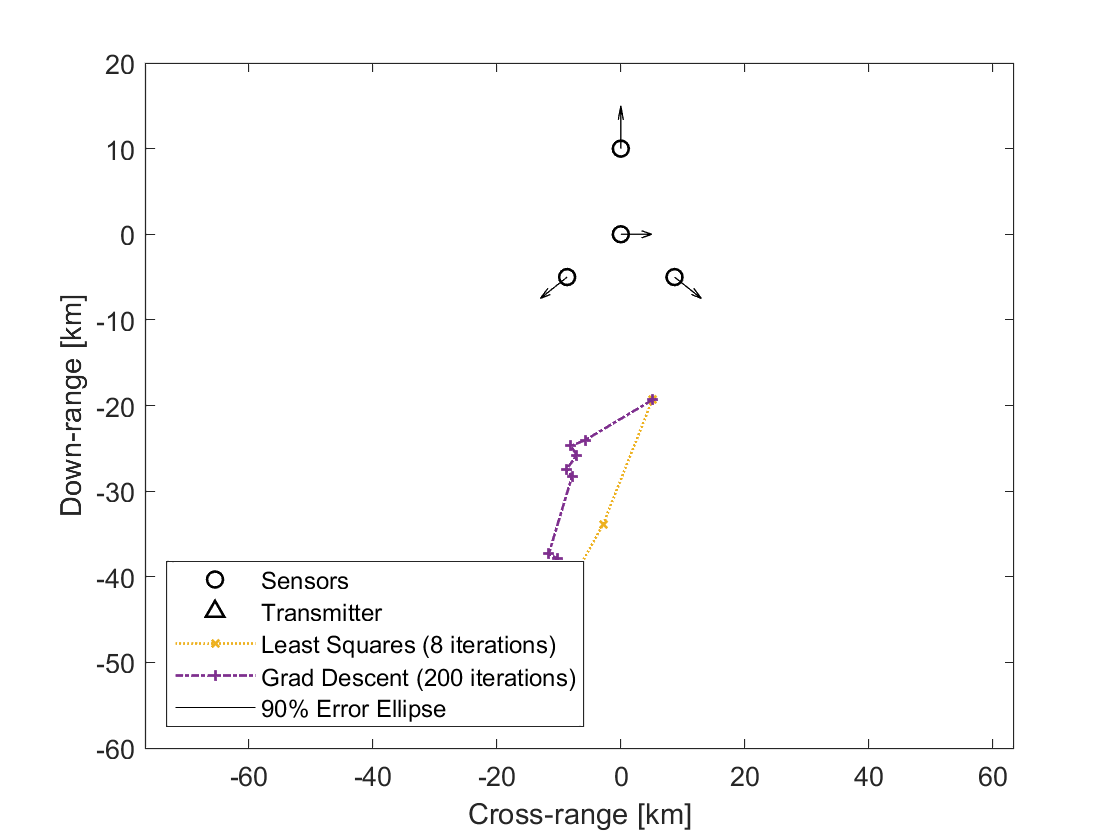

% Plot Geometry
numIterToPlot=min(20,numel(plotIndex));
figure();
plot(x_sensor(1,:)/1e3,x_sensor(2,:)/1e3,'ko','DisplayName','Sensors','LineWidth',1);
hold on;
plot(x_source(1,:)/1e3,x_source(2,:)/1e3,'k^','DisplayName','Transmitter','LineWidth',1);
plot(x_ls_plot(1,1:floor(numIterToPlot/2),1)/1e3,x_ls_plot(2,floor(1:numIterToPlot/2),1)/1e3,':x','DisplayName',sprintf('Least Squares (%d iterations)',plotIndex(floor(numIterToPlot/2))),'LineWidth',1,'MarkerSize',4);
plot(x_grad_plot(1,1:numIterToPlot,1)/1e3,x_grad_plot(2,1:numIterToPlot,1)/1e3,'-.+','DisplayName',sprintf('Grad Descent (%d iterations)',plotIndex(numIterToPlot)),'LineWidth',1,'MarkerSize',4);
set(gca,'ColorOrderIndex',3);
plot(crlb_ellipse(1,:)/1e3,crlb_ellipse(2,:)/1e3,'k','LineWidth',.5,'DisplayName','90% Error Ellipse');

% Draw Velocity Arrows
for idx_sensor = 1:size(x_sensor,2)
    thisX = x_sensor(:,idx_sensor);
    thisV = v_sensor(:,idx_sensor)/norm(v_sensor(:,idx_sensor));
    utils.drawArrow(thisX(1)/1e3+[0 thisV(1)]*5,thisX(2)/1e3+[0 thisV(2)]*5);
end

xlabel('Cross-range [km]');ylabel('Down-range [km]');
legend('Location','SouthWest');
wd = 7*baseline/1e3;
xlim([-1 1]*wd+x_source(1)/1e3/2);
grid off;

## Second Subfigure

The second subfigure is a zoomed-in look at the source position, with the final estimate for LS, GD, and BestFix annotated.

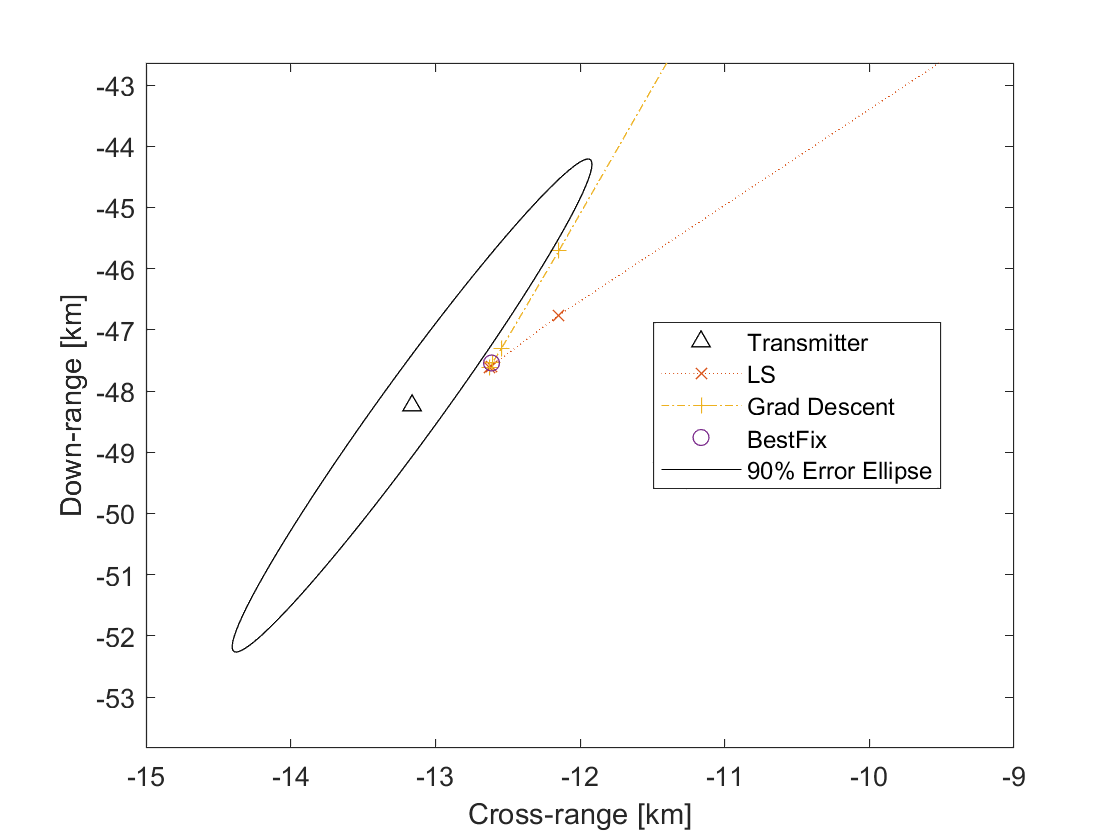

% Plot zoomed geometry
fig_geo_b=figure;
plot(x_source(1,:)/1e3,x_source(2,:)/1e3,'k^','DisplayName','Transmitter');
hold on;
plot(x_ls_plot(1,1:floor(numIterToPlot/2),1)/1e3,x_ls_plot(2,1:floor(numIterToPlot/2),1)/1e3,':x','DisplayName','LS');
plot(x_grad_plot(1,1:numIterToPlot,1)/1e3,x_grad_plot(2,1:numIterToPlot,1)/1e3,'-.+','DisplayName','Grad Descent');
plot(x_bf(1,1)/1e3,x_bf(2,1)/1e3,'o','DisplayName','BestFix');
plot(crlb_ellipse(1,:)/1e3,crlb_ellipse(2,:)/1e3,'k','LineWidth',.5,'DisplayName','90% Error Ellipse');

wd = 8*max(abs(crlb_ellipse(1,:)-x_source(1)));
ht=wd*9/16;
ylim([-1 1]*ht/1e3+x_source(2)/1e3);
xlabel('Cross-range [km]');ylabel('Down-range [km]');
legend('Location','best');
grid off;

## Third Subfigure

This plot shows the average geolocation error across Monte Carlo trials, as a function of iteration number for the iterative solvers.

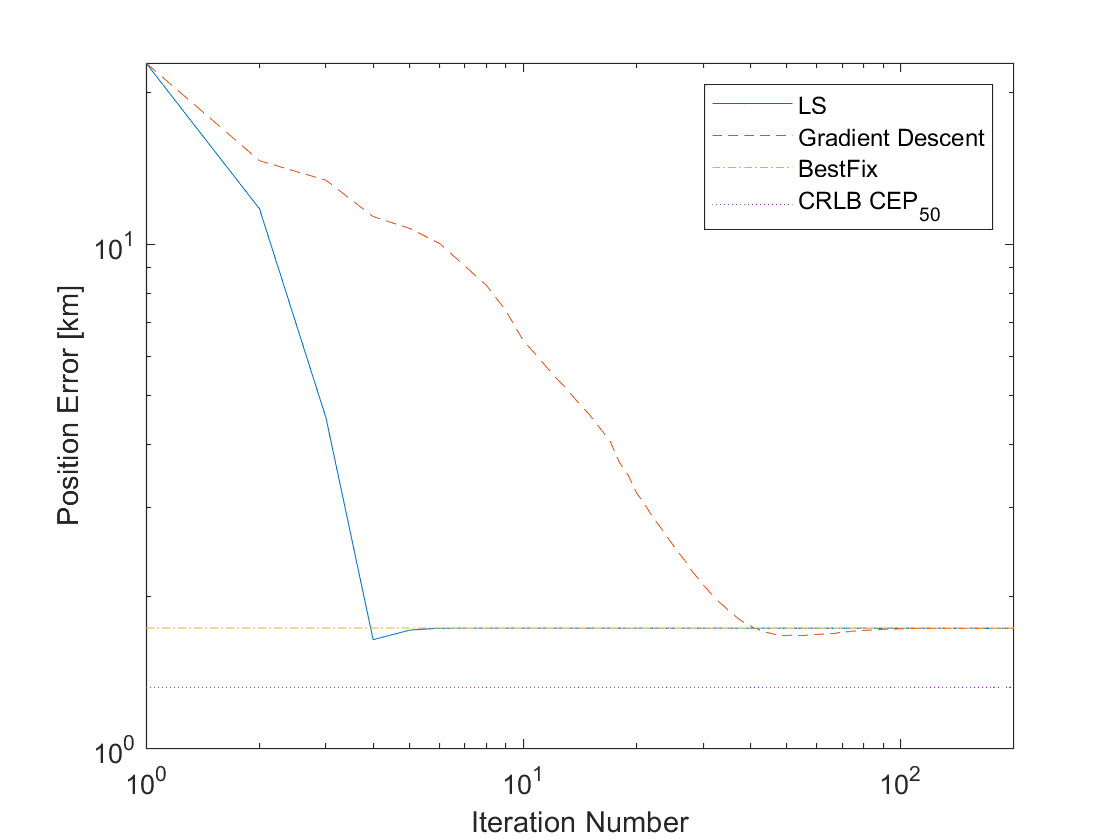

% Plot Error
fig_err=figure;
plot(1:numIters,cep50_ls,'DisplayName','LS');
hold on;
plot(1:numIters,cep50_grad,'--','DisplayName','Gradient Descent');
plot(1:numIters,cep50_bf*ones(1,numIters),'-.','DisplayName','BestFix');
plot(1:numIters,crlb_cep50*ones(1,numIters),':','DisplayName','CRLB CEP_{50}');
xlabel('Iteration Number');
ylabel('Position Error [km]');
set(gca,'yscale','log');
set(gca,'xscale','log');
legend('Location','NorthEast');
xlim([1,numIters]);